## Identifying a model for a PMSM

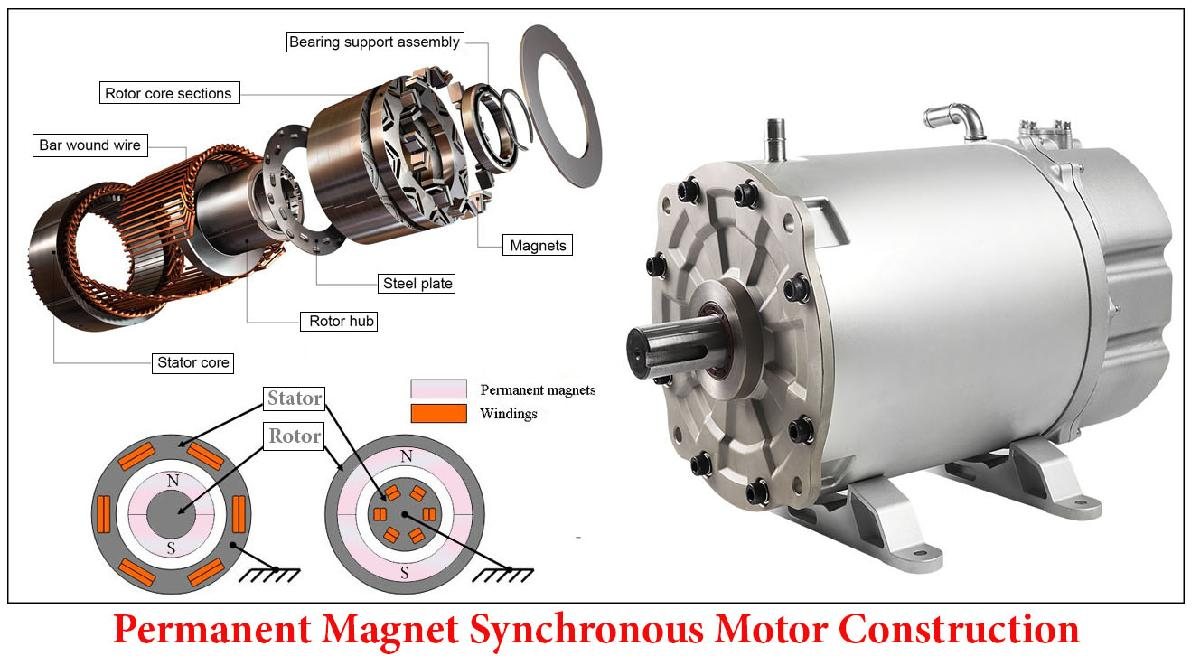

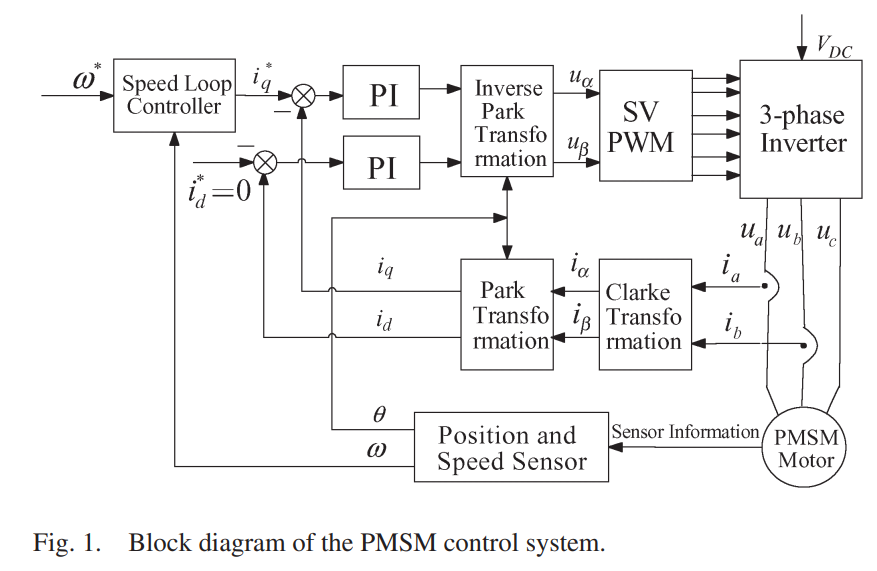

From Liu and Li "Speed control for PMSM Servo system" IEEE tr Ind Elec Vol 59, 2012

The motor is governed by the following system of differential equations

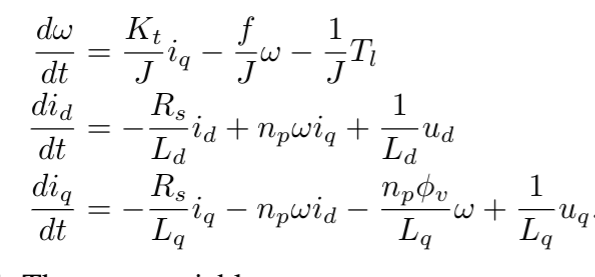

## Generate input data

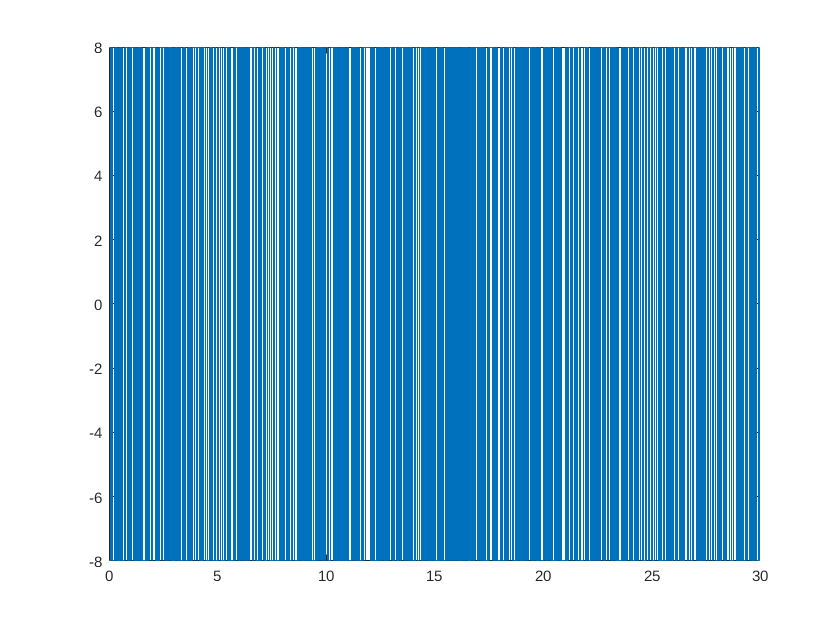


h = 0.01;
uu = idinput(6000, 'rbs', [0, 0.4]);
currentMagnitude = 8;
u1 = currentMagnitude*uu(1:3000);
u1v = currentMagnitude*uu(3001:6000);
t = (1:3000)'*h;
figure()
stairs(t, u1)

input1 = cat(2, t, u1);
input1v = cat(2, t, u1v);


## Load data

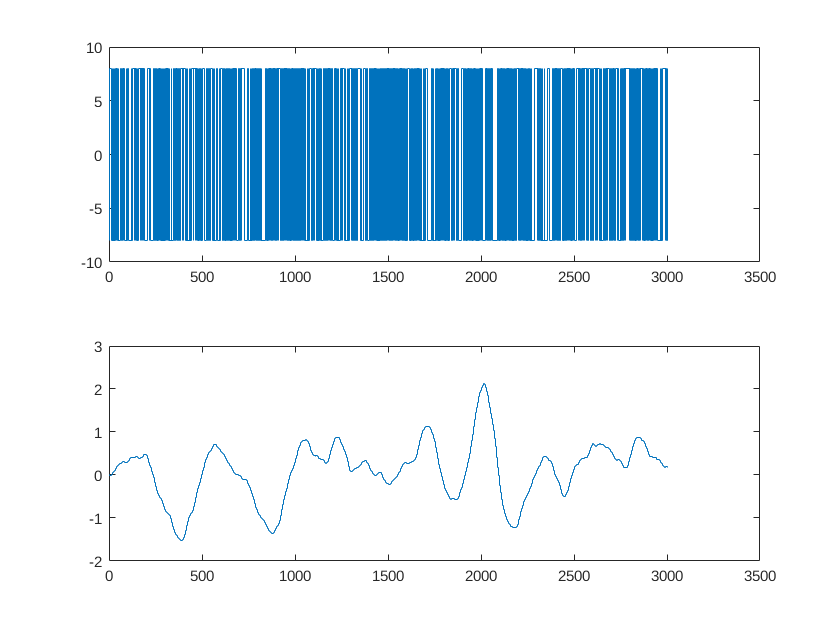



load pmsm_sysid_sim.mat
uident = uy.Data(:,1);
yident = uy.Data(:,2);
figure()
subplot(211);
stairs(uident)
subplot(212)
stairs(yident)

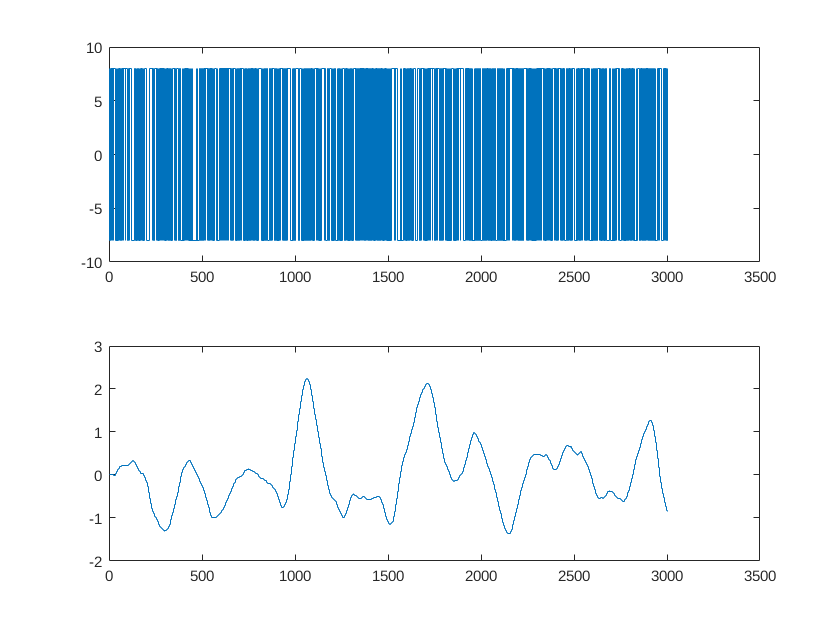


load pmsm_sysid_val_sim.mat
uval = uy.Data(:,1);
yval = uy.Data(:,2);
figure()
subplot(211);
stairs(uval)
subplot(212)
stairs(yval)

## Estimate models

iddta1 = iddata(yident,uident, h);
valdta1 = iddata(yval, uval, h);

% Second order model, one zero, two poles, one delay
% H(z) = (b0 z + b1) / (z^2 + a1z + a2)
arx221 = arx(iddta1, [2, 2, 1])

arx221 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.997 z^-1 + 0.9969 z^-2              
                                                   
  B(z) = -5.06e-06 z^-1 + 7.893e-05 z^-2           
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.92% (prediction focus)
FPE: 2.798e-07, MSE: 2.787e-07                   



% Second order model, one zero, two poles, two delays
% (b0 z + b1) /(z*(z^2 + a1z + a2))
arx222 = arx(iddta1, [2, 2, 2])

arx222 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.995 z^-1 + 0.9951 z^-2              
                                                   
  B(z) = 5.151e-05 z^-2 + 4.636e-05 z^-3           
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=2
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.94% (prediction focus)
FPE: 1.829e-07, MSE: 1.822e-07                   



% fourth order model, three zeros, four poles, one delay
% (b0 z^3 + b1z^2 + b2z + b3) / (z^4 + a1z^3 + a2z^2 + a3z + a4)
arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                       
  A(z) = 1 - 2.979 z^-1 + 3.02 z^-2 - 1.1 z^-3 + 0.05929 z^-4             
                                                                          
  B(z) = 4.815e-06 z^-1 + 4.396e-05 z^-2 - 2.374e-06 z^-3 - 3.879e-05 z^-4
                                                                          
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.98% (prediction focus)
FPE: 2.47e-08, MSE: 2.45e-08                     


arx442 = arx(iddta1, [4, 4, 2])

arx442 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                      
  A(z) = 1 - 3.135 z^-1 + 3.5 z^-2 - 1.593 z^-3 + 0.2278 z^-4            
                                                                         
  B(z) = 4.65e-05 z^-2 - 9.537e-06 z^-3 - 3.973e-05 z^-4 + 9.888e-06 z^-5
                                                                         
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=2
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.98% (prediction focus)
FPE: 2.474e-08, MSE: 2.455e-08                   


arx431 = arx(iddta1, [4, 3, 1])

arx431 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)            
  A(z) = 1 - 2.999 z^-1 + 3.312 z^-2 - 1.625 z^-3 + 0.3118 z^-4
                                                               
  B(z) = 7.717e-06 z^-1 + 4.482e-05 z^-2 - 1.601e-05 z^-3      
                                                               
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=3   nk=1
   Number of free coefficients: 7
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.96% (prediction focus)
FPE: 5.818e-08, MSE: 5.775e-08                   



% sixth order model, five zeros, six poles, one delay
arx661 = arx(iddta1, [6, 6, 1])

arx661 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                         
  A(z) = 1 - 3.102 z^-1 + 3.29 z^-2 - 1.145 z^-3 - 0.1766 z^-4 + 0.1405 z^-5 - 0.006869 z^-6                
                                                                                                            
  B(z) = 4.706e-06 z^-1 + 4.363e-05 z^-2 - 8.103e-06 z^-3 - 4.405e-05 z^-4 + 9.912e-06 z^-5 + 4.105e-06 z^-6
                                                                                                            
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.98% (prediction focus)
FPE: 2.355e-08, MSE: 2.327e-08                   



% eigth order model, seven zeros, eight poles, one delay
arx881 = arx(iddta1, [8, 8, 1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                
                                                                                                                   
  A(z) = 1 - 3.096 z^-1 + 3.283 z^-2 - 1.177 z^-3 - 0.1418 z^-4 + 0.2014 z^-5 - 0.08536 z^-6 - 0.003236 z^-7       
                                                                                                     + 0.01942 z^-8
                                                                                                                   
                                                                                                                   
  B(z) = 4.706e-06 z^-1 + 4.356e-05 z^-2 - 7.88e-06 z^-3 - 4.351e-05 z^-4 + 8.825e-06 z^-5 + 1.385e-06 z^-6        
                                                                                  + 3.473e-07 z^-7 + 3.992e-06 z^-8
                                                               


% 12th order model, 
arx12121 = arx(iddta1, [12, 12, 1])

arx12121 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                
                                                                                                                   
  A(z) = 1 - 3.072 z^-1 + 3.225 z^-2 - 1.135 z^-3 - 0.1345 z^-4 + 0.1113 z^-5 + 0.04285 z^-6 - 0.06888 z^-7        
                                        + 0.06141 z^-8 + 0.05092 z^-9 - 0.2032 z^-10 + 0.1481 z^-11 - 0.02627 z^-12
                                                                                                                   
                                                                                                                   
  B(z) = 4.725e-06 z^-1 + 4.365e-05 z^-2 - 6.869e-06 z^-3 - 4.296e-05 z^-4 + 8.512e-06 z^-5 + 2.003e-06 z^-6       
            - 1.95e-06 z^-7 + 2.742e-07 z^-8 + 3.172e-07 z^-9 + 7.876e-08 z^-10 + 4.916e-06 z^-11 + 2.748e-06 z^-12
                                                             


arx24241 = arx(iddta1, [24, 24, 1])

arx24241 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                   
                                                                                                                      
  A(z) = 1 - 3.021 z^-1 + 3.027 z^-2 - 0.8984 z^-3 - 0.1951 z^-4 + 0.059 z^-5 + 0.07319 z^-6 - 0.08319 z^-7           
          + 0.056 z^-8 + 0.1897 z^-9 - 0.2144 z^-10 - 0.4245 z^-11 + 0.5126 z^-12 + 0.1105 z^-13 - 0.1877 z^-14       
          - 0.07322 z^-15 + 0.1328 z^-16 - 0.1294 z^-17 + 0.1356 z^-18 - 0.01882 z^-19 - 0.08344 z^-20 - 0.1078 z^-21 
                                                                      + 0.2193 z^-22 - 0.0641 z^-23 - 0.01406 z^-24   
                                                                                                                      
                                                                                                                      
  B(z) = 4.758e-06 z^-1 + 4.363e-05 z

arx48481 = arx(iddta1, [48, 48, 1])

arx48481 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                     
                                                                                                                        
  A(z) = 1 - 2.981 z^-1 + 2.903 z^-2 - 0.797 z^-3 - 0.1814 z^-4 + 0.03143 z^-5 + 0.06065 z^-6 - 0.07766 z^-7            
          + 0.08224 z^-8 + 0.1839 z^-9 - 0.2356 z^-10 - 0.4527 z^-11 + 0.4671 z^-12 + 0.2162 z^-13 - 0.1463 z^-14       
          - 0.1477 z^-15 + 0.1165 z^-16 - 0.09858 z^-17 + 0.155 z^-18 - 0.005677 z^-19 - 0.1425 z^-20 - 0.1413 z^-21    
          + 0.09726 z^-22 + 0.217 z^-23 - 0.006932 z^-24 - 0.1584 z^-25 + 0.01091 z^-26 + 0.07275 z^-27 - 0.05985 z^-28 
          + 0.1599 z^-29 - 0.1902 z^-30 - 0.1588 z^-31 + 0.2339 z^-32 - 0.001909 z^-33 + 0.08182 z^-34 - 0.1406 z^-35   
          + 0.0617 z^-36 - 0.1241 z^-37 + 0.2494 z^-38 - 0.2288 z^-39 + 0.1044 z^-40 - 0.09281 z^-41 + 0.04036 z^-42    
                 + 0.

## Compare models

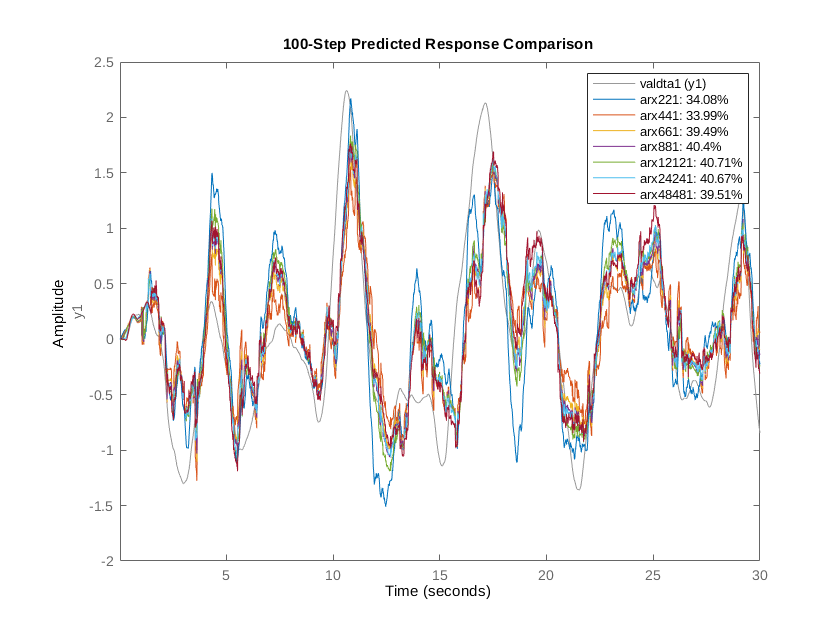

figure()
compare(valdta1, arx221, arx441,arx661,arx881, arx12121,arx24241, arx48481, 100)

aic(arx221, arx441, arx661, arx12121, arx24241, arx48481)

Model quality according to the "nAIC" measure:
  -15.0890  -17.5165  -17.5642  -17.5888  -17.6912  -17.7229



## Export models for use in Simulink

[num, den] = tfdata(tf(arx441))

num = 1×1 cell array
    {[0 4.8154e-06 4.3958e-05 -2.3739e-06 -3.8785e-05]}


den = 1×1 cell array
    {[1 -2.9794 3.0200 -1.0998 0.0593]}


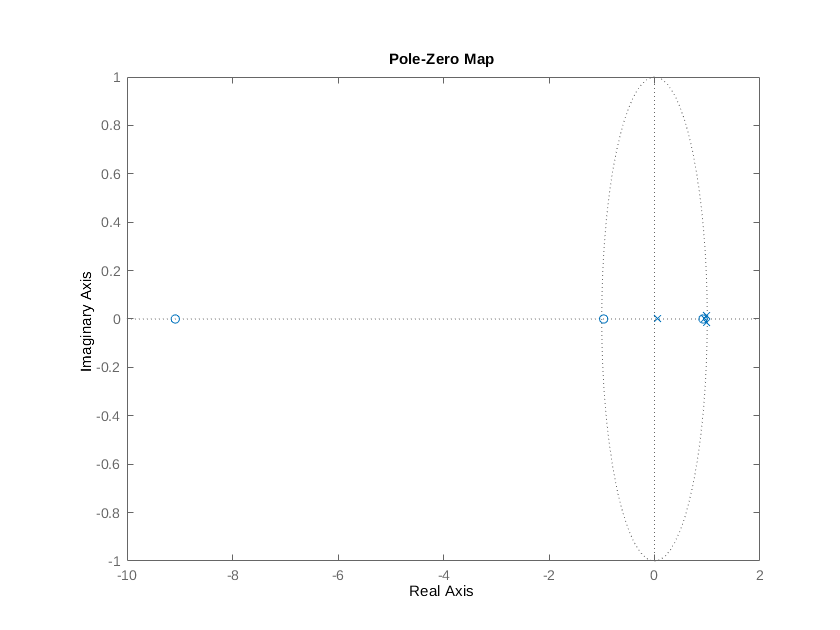

pzmap(tf(arx441))